x = [0,10,10,10];
y = [0,0,10,10];

path = Path(x,y,0.5,0.001);
len = path.getLength()

len = 11.6232

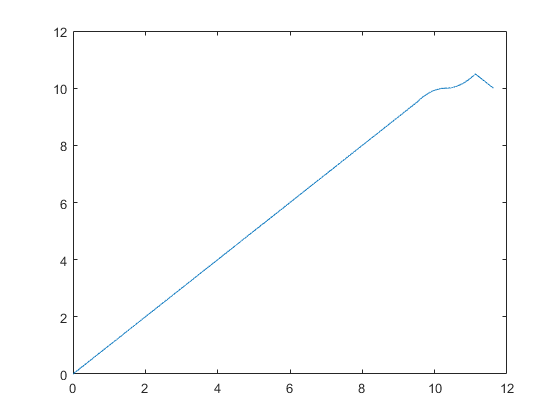

s = [0:.001:len];

[x1,y1] = path.getPoint(s);
figure();
%plot(x1,y1)
%hold on;
% figure()
plot(s,x1)

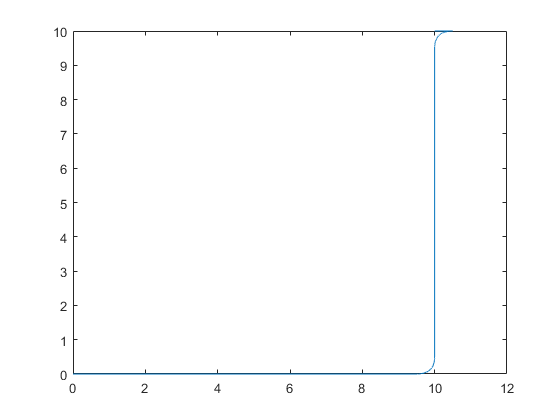

plot()

plot(path.sub);

Unrecognized method, property, or field 'sub' for class 'Path'.

grid minor
% figure();

[xt,yt] = path.diff(s,1)

Index exceeds the number of array elements (5).

Error in Path/getSubsplineToPoint (line 75)
                while s_offset(i) - obj.subsplines(idx(i)).length > 0

Error in Path/getPoint (line 50)
            [idx, s_offset] = obj.getSubsplineToPoint(s);

Error in 

%[xtt,ytt] = path.diff(s,2)
figure();
plot(s,xt)
hold on;
plot(s,yt)
figure();
%plot(s,xtt)
%hold on;
%plot(s,ytt)

b = BezierCurve(x,y,2,0.01)

b =   BezierCurve with properties:

     startPoint: [1×1 struct]
       endPoint: [1×1 struct]
              r: 2
             dx: 0.0100
    curvePoints: [1×1 struct]


b.getLength()

ans = 3.2464


s = [0:.001:1];
[xt,yt] = b.getPoint(s)                     

xt =     8.0000
    8.0040
    8.0080
    8.0120
    8.0160
    8.0199
    8.0239
    8.0279
    8.0319
    8.0358


yt =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0002


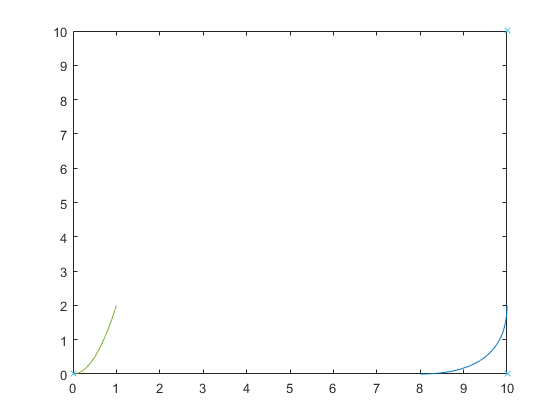

% figure();
plot(s,yt);
hold on
plot([0,10,10],[0,0,10],"x")